data = readtable('LOB_data.csv');
data

data = 438673×12 table
    MsgType    SeqNumber     Symbol     SourceTime    SymbolSeqnum     OrderID      Price     Volume    Side     FirmID    NumParitySplits    len_firmid
    _______    _________    ________    __________    ____________    __________    ______    ______    _____    ______    _______________    __________

      100        12395      {'AAPL'}     07:00:00           4         1.7733e+16     135.2       5      {'B'}     NaN             0               0     
      100        13035      {'AAPL'}     07:00:49           5         1.7733e+16    141.82     100      {'S'}

LOB = data(:, {'Price','SourceTime','Volume', 'Side'});

Bid = LOB(strcmp(LOB.Side, 'S'),:);
Ask = LOB(strcmp(LOB.Side, 'B'),:);

% Before Removing Outliersn
plt1 = plot(Bid.SourceTime, Bid.Price, 'Color','blue');
title('Bid Price before Removing Outliersn','Color','blue');
plt2 = plot(Ask.SourceTime, Ask.Price, 'Color','red');
title('Ask Price before Removing Outliersn','Color','red');
plt3 = plot(Bid.SourceTime, Bid.Volume, 'Color','blue');
title('Bid Volume before Removing Outliers','Color','blue');
plt4 = plot(Ask.SourceTime, Ask.Volume, 'Color','red');
title('Ask Volume before Removing Outliers','Color','red');

% Remove Outliers
Bid_woutOutliers = removeOutliers(Bid)

Bid_woutOutliers = 251105×4 table
    Price     Volume    SourceTime    Side 
    ______    ______    __________    _____

    141.82     100       07:00:49     {'S'}
    141.76     100       07:01:22     {'S'}
    141.69     100       07:01:33     {'S'}
    141.68     100       07:02:35     {'S'}
    141.67     100       07:02:37     {'S'}
    141.66     100       07:03:08     {'S'}
    141.61     100       07:03:47     {'S'}
    141.61     100       07:03:49     {'S'}
    141.55     100       07:05:14     {'S'}
    141.56     100       07:05:15     {'S'}
    141.54     100       07:11:37     {'S'}
    141.44     100       07:12:59     {'S'}
    141.34     100       07:13:53     {'S'}
    141.34     100       07:13:56     {'S'}
    141.31     100       07:14:00     {'S'}
    141.29     100       07:14:08     {'S'}


Ask_woutOutliers = removeOutliers(Ask)

Ask_woutOutliers = 187568×4 table
    Price     Volume    SourceTime    Side 
    ______    ______    __________    _____

     135.2       5       07:00:00     {'B'}
    141.71     100       07:00:55     {'B'}
    141.58     100       07:03:10     {'B'}
    141.48     100       07:11:47     {'B'}
     141.3     100       07:14:12     {'B'}
     140.9     100       07:17:00     {'B'}
    141.81      21       09:05:22     {'B'}
    141.81      80       09:05:22     {'B'}
    141.81     106       09:05:22     {'B'}
    134.36     100       09:10:08     {'B'}
    141.75      80       09:25:10     {'B'}
    141.75     106       09:25:17     {'B'}
    141.58     100       09:29:27     {'B'}
    139.39     100       09:30:00     {'B'}
    136.67     100       09:30:00     {'B'}
    140.11     100       09:30:00     {'B'}


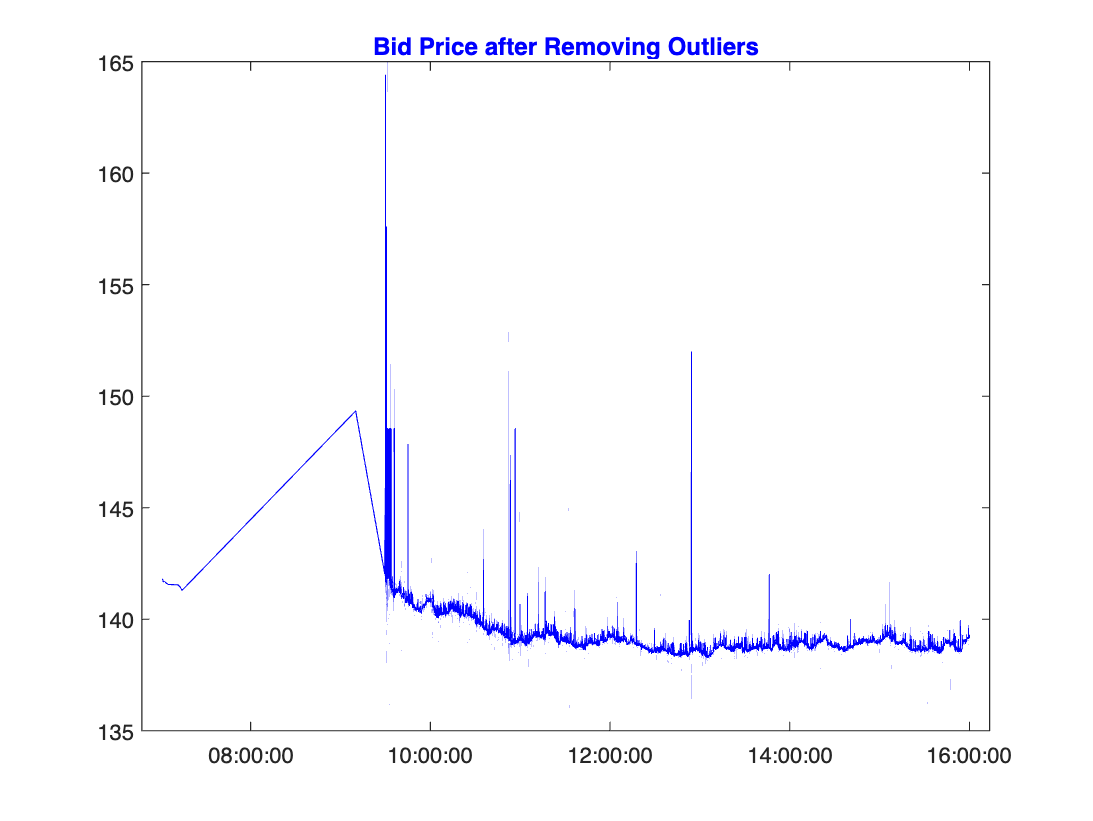


% After Removing Outliers
plt_1 = plot(Bid_woutOutliers.SourceTime, Bid_woutOutliers.Price, 'Color','blue');
title('Bid Price after Removing Outliers','Color','blue');

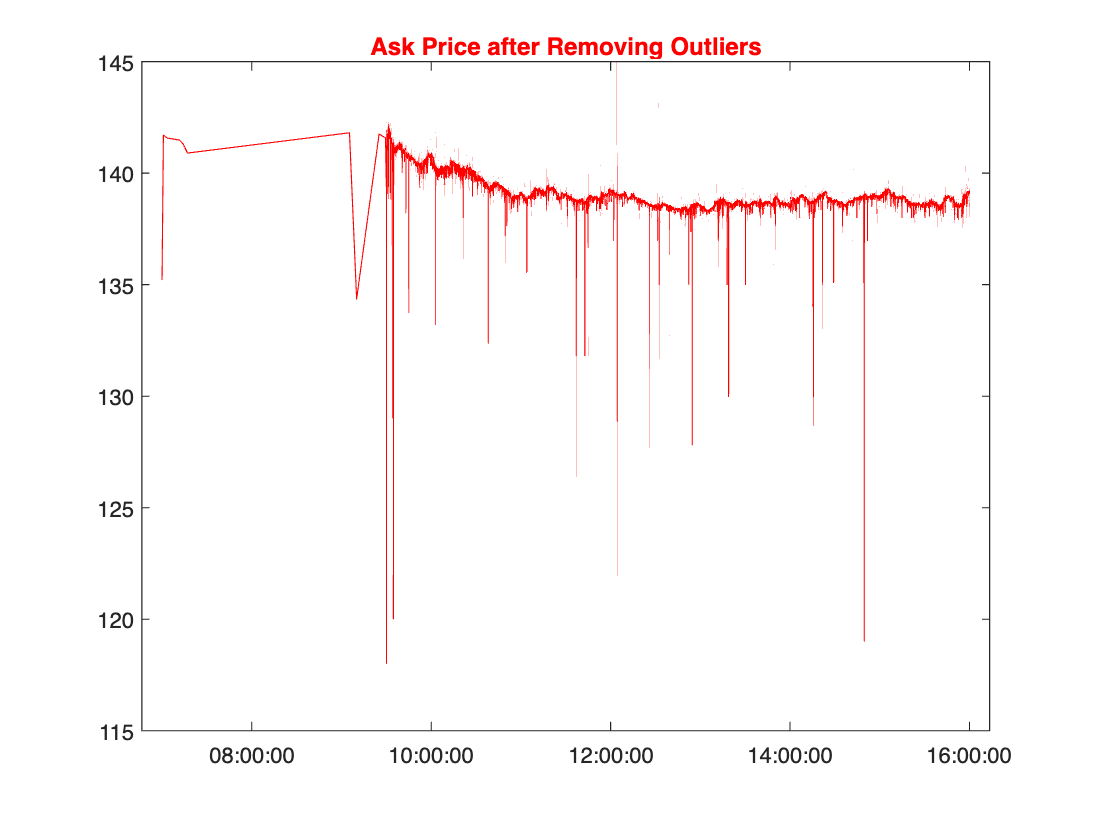

plt_2 = plot(Ask_woutOutliers.SourceTime, Ask_woutOutliers.Price,'Color','red');
title('Ask Price after Removing Outliers','Color','red');

plt_3 = plot(Bid_woutOutliers.SourceTime, Bid_woutOutliers.Volume, 'Color','blue');
title('Bid Volume after Removing Outliers','Color','blue');
plt_4 = plot(Ask_woutOutliers.SourceTime, Ask_woutOutliers.Volume, 'Color','red');
title('Ask Volume after Removing Outliers','Color','red');



weighted_Bid = weight_Calculation(Bid_woutOutliers)

weighted_Bid = 20548×2 table
    SourceTime    WeightedAverage
    __________    _______________

     07:00:49         141.82     
     07:01:22         141.76     
     07:01:33         141.69     
     07:02:35         141.68     
     07:02:37         141.67     
     07:03:08         141.66     
     07:03:47         141.61     
     07:03:49         141.61     
     07:05:14         141.55     
     07:05:15         141.56     
     07:11:37         141.54     
     07:12:59         141.44     
     07:13:53         141.34     
     07:13:56         141.34     
     07:14:00         141.31     
     07:14:08         141.29     


weighted_Bid = renamevars(weighted_Bid,"WeightedAverage", 'Weighted_Bid_Price');
weighted_Ask = weight_Calculation(Ask_woutOutliers)

weighted_Ask = 19875×2 table
    SourceTime    WeightedAverage
    __________    _______________

     07:00:00          135.2     
     07:00:55         141.71     
     07:03:10         141.58     
     07:11:47         141.48     
     07:14:12          141.3     
     07:17:00          140.9     
     09:05:22         141.81     
     09:10:08         134.36     
     09:25:10         141.75     
     09:25:17         141.75     
     09:29:27         141.58     
     09:30:00         137.08     
     09:30:01         141.41     
     09:30:02         140.79     
     09:30:03         141.63     
     09:30:04          140.2     


weighted_Ask = renamevars(weighted_Ask,"WeightedAverage", 'Weighted_Ask_Price');
Weighted_LOB = innerjoin(weighted_Bid,weighted_Ask)

Weighted_LOB = 18129×3 table
    SourceTime    Weighted_Bid_Price    Weighted_Ask_Price
    __________    __________________    __________________

     09:10:08           149.34                134.36      
     09:29:27           142.07                141.58      
     09:30:00           147.63                137.08      
     09:30:01           142.14                141.41      
     09:30:02           141.88                140.79      
     09:30:03           141.84                141.63      
     09:30:04              NaN                 140.2      
     09:30:05            141.7                141.68      
     09:30:07           142.27                141.44      
     09:30:08           145.99                140.38      
     09:30:09           146.67                 141.6      
     09:30:10           143.64                141.73      
     09:30:11           144.16            


% Midprice calculation
Weighted_LOB.MidPrice = (Weighted_LOB.Weighted_Bid_Price + Weighted_LOB.Weighted_Ask_Price) / 2

Weighted_LOB = 18129×4 table
    SourceTime    Weighted_Bid_Price    Weighted_Ask_Price    MidPrice
    __________    __________________    __________________    ________

     09:10:08           149.34                134.36           141.85 
     09:29:27           142.07                141.58           141.82 
     09:30:00           147.63                137.08           142.36 
     09:30:01           142.14                141.41           141.77 
     09:30:02           141.88                140.79           141.34 
     09:30:03           141.84                141.63           141.73 
     09:30:04              NaN                 140.2              NaN 
     09:30:05            141.7                141.68           141.69 
     09:30:07           142.27                141.44           141.85 
     09:30:08           145.99                140.38 


% Calculate the state of the price
States = cell(height(Weighted_LOB),1);
States(:) = {'Static'};  %Default
Weighted_LOB.State = categorical(States);

for i = 2:numel(Weighted_LOB.MidPrice)
    if Weighted_LOB.MidPrice(i) > Weighted_LOB.MidPrice(i-1)
        Weighted_LOB.State(i) = 'Up';
    elseif Weighted_LOB.MidPrice(i) < Weighted_LOB.MidPrice(i-1)
        Weighted_LOB.State(i) = 'Down';
    else
        Weighted_LOB.State(i) = 'Static';
    end
end

% Specify the file path for the CSV file in the current folder
filePath = 'weightedLOB.csv';

% Write the table to the CSV file
writetable(Weighted_LOB, filePath);

disp(['Table has been written to: ' filePath]);

Table has been written to: weightedLOB.csv


function cleanedData = removeOutliers(data)
 
    % Extract numeric data for normalization
    numericData = table2array(data(:, {'Price', 'Volume'}));

    % Define a threshold for identifying outliers
    threshold1 = 200;
    threshold2 = 80;
    threshold3 = 9000;

    % Remove outliers for 'Price' column
    priceColumn = numericData(:, 1);  
    outliers_price1 = priceColumn > threshold1;  % larger than 200
    outliers_price2 = priceColumn < threshold2;  % smaller than 80
    priceColumn(outliers_price1) = NaN;
    priceColumn(outliers_price2) = NaN;

    % Replace outliers with MAD for 'Volume' column
    volumeColumn = numericData(:, 2);
    outliers_volume = volumeColumn > threshold3; 
    volumeColumn(outliers_volume) = NaN;

    % Update the modified columns in the numericData matrix
    numericData(:, 1) = priceColumn;
    numericData(:, 2) = volumeColumn;

    normalizedLOB = array2table(numericData, 'VariableNames', {'Price', 'Volume'});
 
    % Combine the normalized numeric columns with the non-numeric columns
    cleanedData = [normalizedLOB, data(:, 'SourceTime'), data(:, 'Side')];
end


function  weightedPrice = weight_Calculation(data)

    % Time index
    [~,~,index] = unique(data.SourceTime);
    data.NumericTime = index;

    % Calculate group sum of volume
    groupSums = splitapply(@sum, data.Volume, data.NumericTime);

    % Add the 'GroupSum' column to the dataset
    data.GroupSum = groupSums(index);
    data.Weight = data.Volume ./ data.GroupSum;
    data.WeightedPrice = data.Price .* data.Weight;
    SourceTime = unique(data.SourceTime);
    WeightedAverage = splitapply(@sum, data.WeightedPrice, data.NumericTime);

    % Create a new table with the results
    weightedPrice = table(SourceTime, WeightedAverage);

end
